%Create Codebook
[s1,Fs(1)] = audioread('./Training_Data/s1.wav');
[s2,Fs(2)] = audioread('./Training_Data/s2.wav');
[s3,Fs(3)] = audioread('./Training_Data/s3.wav');
[s4,Fs(4)] = audioread('./Training_Data/s4.wav');
[s5,Fs(5)] = audioread('./Training_Data/s5.wav');
[s6,Fs(6)] = audioread('./Training_Data/s6.wav');
[s7,Fs(7)] = audioread('./Training_Data/s7.wav');
[s8,Fs(8)] = audioread('./Training_Data/s8.wav');
[s9,Fs(9)] = audioread('./Training_Data/s9.wav');
[s10,Fs(10)]= audioread('./Training_Data/s10.wav');
[s11,Fs(11)] = audioread('./Training_Data/s11.wav');



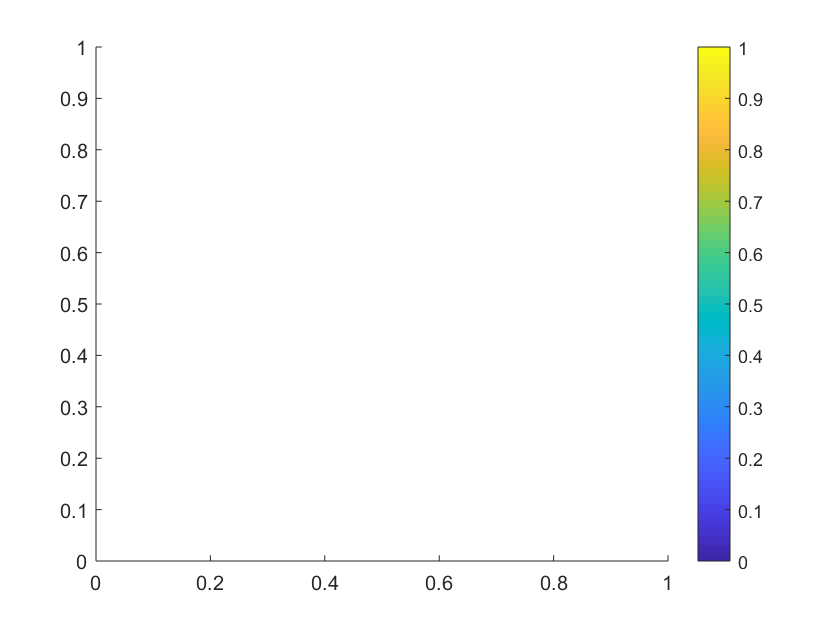

nfilt = 26;
norm = 'y';
lift = 'l';
[cepsCoeff1] = mfcc(s1,Fs(1),nfilt,norm,lift);
[cepsCoeff2] = mfcc(s2,Fs(2),nfilt,norm,lift);
[cepsCoeff3] = mfcc(s3,Fs(3),nfilt,norm,lift);
[cepsCoeff4] = mfcc(s4,Fs(4),nfilt,norm,lift);
[cepsCoeff5] = mfcc(s5,Fs(5),nfilt,norm,lift);
[cepsCoeff6] = mfcc(s6,Fs(6),nfilt,norm,lift);
[cepsCoeff7] = mfcc(s7,Fs(7),nfilt,norm,lift);
[cepsCoeff8] = mfcc(s8,Fs(8),nfilt,norm,lift);
[cepsCoeff9] = mfcc(s9,Fs(9),nfilt,norm,lift);
[cepsCoeff10] = mfcc(s10,Fs(10),nfilt,norm,lift);
[cepsCoeff11] = mfcc(s11,Fs(11),nfilt,norm,lift);
[cepsCoeff1Noise] = mfcc(awgn(s1,40,'measured'),Fs(1),nfilt,norm,lift);


[cepsCoeff1] = generateCepstrum(normalize(s1),Fs(1));

    83



[cepsCoeff2] = generateCepstrum(normalize(s2),Fs(2));

    86



[cepsCoeff3] = generateCepstrum(normalize(s3),Fs(3));

    84



[cepsCoeff4] = generateCepstrum(normalize(s4),Fs(4));

    94



[cepsCoeff5] = generateCepstrum(normalize(s5),Fs(5));

   115



[cepsCoeff6] = generateCepstrum(normalize(s6),Fs(6));

    94



[cepsCoeff7] = generateCepstrum(normalize(s7),Fs(7));

    91



[cepsCoeff8] = generateCepstrum(normalize(s8),Fs(8));

    92



[cepsCoeff9] = generateCepstrum(normalize(s9),Fs(9));

   161



[cepsCoeff10] = generateCepstrum(normalize(s10),Fs(10));

   177



[cepsCoeff11] = generateCepstrum(normalize(s11),Fs(11));

   131



[cepsCoeff1Noise] = generateCepstrum(normalize(awgn(s1,40,'measured')),Fs(1));

    83



%{
plot([1:26],mean(cepsCoeff1(:,[1:26])));
hold on;
plot([1:26],mean(cepsCoeff2(:,[1:26])));
plot([1:26],mean(cepsCoeff3(:,[1:26])));
plot([1:26],mean(cepsCoeff4(:,[1:26])));
plot([1:26],mean(cepsCoeff5(:,[1:26])));
plot([1:26],mean(cepsCoeff6(:,[1:26])));
plot([1:26],mean(cepsCoeff7(:,[1:26])));
plot([1:26],mean(cepsCoeff8(:,[1:26])));
plot([1:26],mean(cepsCoeff9(:,[1:26])));
plot([1:26],mean(cepsCoeff10(:,[1:26])));
plot([1:26],mean(cepsCoeff11(:,[1:26])));
legend()
hold off;
%}
%f=figure();
%subplot(1,2,1);
%surf(cepsCoeff1);
%subplot(1,2,2);
%surf(cepsCoeff2);


[c1, p1, DistHist1]=vqsplit(cepsCoeff1',32);

   8.6167e+06

   4.2449e+06

   3.7688e+06

   3.7150e+06

     4

   3.7150e+06

   3.6571e+06

   2.2867e+06

   1.7540e+06

   1.7436e+06

     8

   1.7436e+06

   1.7241e+06

   1.3687e+06

   1.0836e+06

   1.0377e+06

   1.0121e+06

    16

   1.0121e+06

   1.0025e+06

   8.2691e+05

   5.6141e+05

   4.8299e+05

   4.5536e+05

    32

   4.5536e+05

   2.3292e+05

   2.1233e+05

   1.9313e+05

   1.9064e+05

   1.8968e+05

   1.8767e+05

   1.8692e+05

   1.8692e+05

Iterations = 30
Split = 4


[c2, p2, DistHist2]=vqsplit(cepsCoeff2',32);

   9.3956e+06

   3.3474e+06

   3.0633e+06

     4

   3.0633e+06

   3.0053e+06

   1.8986e+06

   1.7814e+06

   1.7651e+06

     8

   1.7651e+06

   1.7429e+06

   1.2022e+06

   8.6394e+05

   8.4378e+05

   8.3494e+05

   8.2533e+05

    16

   8.2338e+05

   8.1132e+05

   5.3814e+05

   4.5435e+05

   4.2238e+05

   4.1404e+05

    32

   4.1404e+05

   2.4026e+05

   2.0929e+05

   2.0623e+05

   2.0565e+05

   2.0565e+05

Iterations = 27
Split = 4


[c3, p3, DistHist3]=vqsplit(cepsCoeff3',32);

   7.6544e+06

   3.9434e+06

   2.8962e+06

   2.8443e+06

     4

   2.8369e+06

   2.7652e+06

   1.2878e+06

   1.1685e+06

   1.1620e+06

     8

   1.1620e+06

   1.1445e+06

   8.6764e+05

   6.1521e+05

   5.7187e+05

   5.6387e+05

   5.5658e+05

    16

   5.5658e+05

   5.4754e+05

   4.1147e+05

   3.6017e+05

   3.5734e+05

   3.5629e+05

    32

   3.5629e+05

   2.3221e+05

   1.9202e+05

   1.8142e+05

   1.8142e+05

Iterations = 27
Split = 4


[c4, p4, DistHist4]=vqsplit(cepsCoeff4',32);

   7.0869e+06

   3.8812e+06

   3.7103e+06

   3.5939e+06

   3.4199e+06

     4

   3.4041e+06

   3.3195e+06

   1.6367e+06

   1.5295e+06

   1.5232e+06

     8

   1.5232e+06

   1.5000e+06

   1.1568e+06

   1.0346e+06

   1.0062e+06

   9.9004e+05

   9.4881e+05

   9.2848e+05

    16

   9.2848e+05

   9.1749e+05

   5.2252e+05

   4.1738e+05

    32

   4.1738e+05

   2.9057e+05

   2.6983e+05

   2.6138e+05

   2.5913e+05

   2.5913e+05

Iterations = 28
Split = 4


[c5, p5, DistHist5]=vqsplit(cepsCoeff5',32);

   1.1525e+07

   4.2400e+06

   4.0789e+06

     4

   4.0740e+06

   4.0079e+06

   2.8457e+06

   2.7878e+06

   2.7699e+06

     8

   2.7699e+06

   2.7401e+06

   1.8905e+06

   1.6957e+06

   1.5044e+06

   1.4035e+06

   1.2990e+06

   1.2579e+06

   1.2412e+06

    16

   1.2397e+06

   1.2237e+06

   6.9520e+05

   5.8380e+05

   5.6757e+05

   5.6494e+05

    32

   5.6494e+05

   5.5732e+05

   3.3045e+05

   3.0027e+05

   3.0027e+05

Iterations = 28
Split = 4


[c6, p6, DistHist6]=vqsplit(cepsCoeff6',32);

   9.3235e+06

   5.6726e+06

   5.6204e+06

   5.5878e+06

   5.4158e+06

   4.9372e+06

   4.8583e+06

     4

   4.8439e+06

   4.7580e+06

   1.8186e+06

   1.5845e+06

     8

   1.5796e+06

   1.5613e+06

   1.1434e+06

   9.3266e+05

   8.5846e+05

   8.4131e+05

   8.3862e+05

    16

   8.3862e+05

   8.2642e+05

   5.2806e+05

   4.6838e+05

   4.5829e+05

    32

   4.5829e+05

   2.8906e+05

   2.5334e+05

   2.4774e+05

   2.4387e+05

   2.4228e+05

   2.4228e+05

Iterations = 30
Split = 4


[c7, p7, DistHist7]=vqsplit(cepsCoeff7',32);

   9.2746e+06

   4.7823e+06

   3.8805e+06

   3.8437e+06

     4

   3.8437e+06

   3.7734e+06

   2.2774e+06

   1.9923e+06

     8

   1.9923e+06

   1.9708e+06

   1.4961e+06

   1.3612e+06

   1.3396e+06

   1.2933e+06

   1.2318e+06

   1.2256e+06

   1.2167e+06

   1.2115e+06

    16

   1.2115e+06

   1.1975e+06

   7.4206e+05

   6.6712e+05

   6.5919e+05

    32

   6.5919e+05

   4.2804e+05

   3.3357e+05

   3.0282e+05

   2.9646e+05

   2.9646e+05

Iterations = 29
Split = 4


[c8, p8, DistHist8]=vqsplit(cepsCoeff8',32);

   7.3104e+06

   3.8907e+06

   3.6150e+06

     4

   3.6059e+06

   3.5556e+06

   2.5100e+06

   2.1645e+06

   2.0036e+06

   1.9443e+06

     8

   1.9443e+06

   1.9212e+06

   1.2561e+06

   1.1001e+06

   1.0223e+06

    16

   1.0195e+06

   1.0067e+06

   6.8783e+05

   6.1824e+05

   5.9298e+05

   5.8602e+05

   5.8476e+05

    32

   5.8403e+05

   3.4393e+05

   2.5646e+05

   2.4359e+05

   2.4359e+05

Iterations = 26
Split = 4


[c9, p9, DistHist9]=vqsplit(cepsCoeff9',32);

   1.1886e+07

   5.1225e+06

     4

   5.1063e+06

   5.0512e+06

   2.9921e+06

   2.7909e+06

   2.7685e+06

   2.7576e+06

   2.7432e+06

   2.7287e+06

     8

   2.7199e+06

   2.6961e+06

   2.0083e+06

   1.8368e+06

   1.7559e+06

   1.5827e+06

   1.2507e+06

   1.2262e+06

   1.2199e+06

   1.2113e+06

   1.2035e+06

    16

   1.2021e+06

   1.1866e+06

   8.6765e+05

   8.1389e+05

   8.0173e+05

   7.7775e+05

   7.7403e+05

   7.7158e+05

    32

   7.7130e+05

   7.6260e+05

   5.2226e+05

   4.8334e+05

   4.6910e+05

   4.6507e+05

   4.6203e+05

   4.5821e+05

   4.5714e+05

   4.5665e+05

Iterations = 39
Split = 4


[c10, p10, DistHist10]=vqsplit(cepsCoeff10',32);

   1.0120e+07

   4.6376e+06

   4.4689e+06

     4

   4.4641e+06

   4.3684e+06

   2.7680e+06

   2.6448e+06

   2.6025e+06

     8

   2.6021e+06

   2.5594e+06

   1.8221e+06

   1.7109e+06

   1.6611e+06

   1.6297e+06

   1.6241e+06

    16

   1.6241e+06

   1.6012e+06

   1.2421e+06

   1.1784e+06

   1.1452e+06

   1.1381e+06

    32

   1.1378e+06

   1.1256e+06

   8.7991e+05

   7.7991e+05

   7.5421e+05

   7.4461e+05

   7.3902e+05

   7.3391e+05

   7.3391e+05

Iterations = 30
Split = 4


[c11, p11, DistHist11]=vqsplit(cepsCoeff11',32);

   1.1041e+07

   4.3454e+06

   4.1112e+06

     4

   4.0973e+06

   4.0251e+06

   2.9943e+06

   2.7127e+06

   2.6848e+06

   2.6697e+06

     8

   2.6607e+06

   2.6027e+06

   1.7425e+06

   1.6480e+06

   1.6029e+06

   1.5682e+06

   1.5558e+06

    16

   1.5551e+06

   1.5284e+06

   1.1130e+06

   1.0456e+06

   1.0086e+06

   9.8770e+05

    32

   9.8674e+05

   9.7469e+05

   6.5251e+05

   6.2053e+05

   6.1837e+05

   6.1837e+05

Iterations = 28
Split = 4



%surf(c1);
%surf(c2);
%f = figure();
%plot(c1())
disp('Finished VQsplit');

Finished VQsplit


[s1,Fs(1)] = audioread('./Training_Data/s1.wav');


soundsc(awgn(s1,5,'measured'),Fs(1));

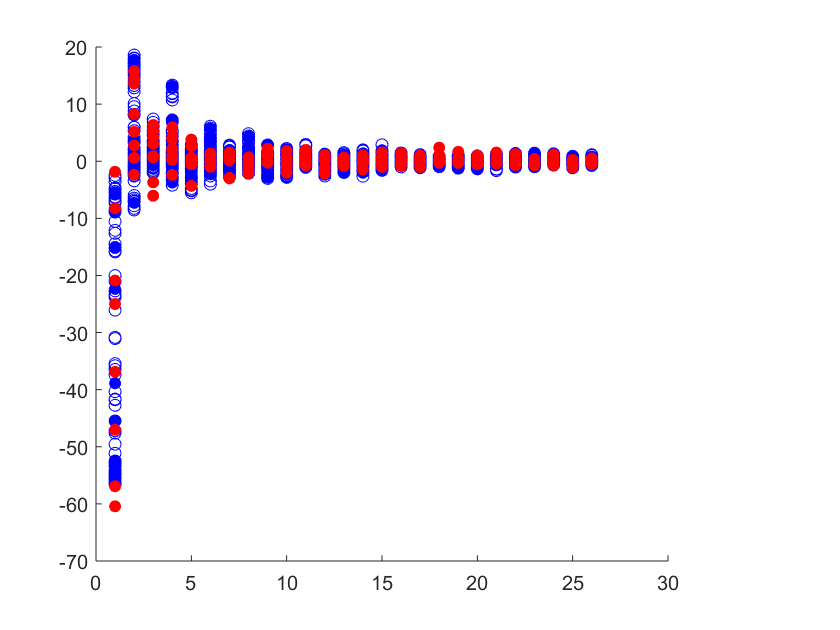

scatter([1:26],c1(:,1)','filled','blue');
hold on;
scatter([1:26],c1(:,2)','filled','blue');
scatter([1:26],c1(:,3)','filled','blue');
scatter([1:26],c1(:,4)','filled','blue');
scatter([1:26],c1(:,5)','filled','blue');
scatter([1:26],c1(:,6)','filled','blue');
scatter([1:26],c1(:,7)','filled','blue');
scatter([1:26],c1(:,8)','filled','blue');
for i = [1:83]
    scatter([1:26],cepsCoeff1(i,:),'blue');
end

scatter([1:26],c2(:,1)','filled','red');
hold on;
scatter([1:26],c2(:,2)','filled','red');
scatter([1:26],c2(:,3)','filled','red');
scatter([1:26],c2(:,4)','filled','red');
scatter([1:26],c2(:,5)','filled','red');
scatter([1:26],c2(:,6)','filled','red');
scatter([1:26],c2(:,7)','filled','red');
scatter([1:26],c2(:,8)','filled','red');
%for i = [1:86]
   % scatter([1:26],cepsCoeff2(i,:),'red');
%end
hold off;


similarityValues1 = similarityToAllCodebooks(cepsCoeff1,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues2 = similarityToAllCodebooks(cepsCoeff2,86,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues3 = similarityToAllCodebooks(cepsCoeff3,84,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues4 = similarityToAllCodebooks(cepsCoeff4,94,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues5 = similarityToAllCodebooks(cepsCoeff5,115,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues6 = similarityToAllCodebooks(cepsCoeff6,94,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues7 = similarityToAllCodebooks(cepsCoeff7,91,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues8 = similarityToAllCodebooks(cepsCoeff8,92,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues9 = similarityToAllCodebooks(cepsCoeff9,161,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues10 = similarityToAllCodebooks(cepsCoeff10,177,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues11 = similarityToAllCodebooks(cepsCoeff11,131,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1Noise = similarityToAllCodebooks(cepsCoeff1Noise,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);

SimilarityNormilizationVector = [83,86,84,94,115,94,91,92,161,177,131];
lastIterationDistortion = [DistHist1(end),DistHist2(end),DistHist3(end),DistHist4(end),DistHist5(end),DistHist6(end),DistHist7(end),DistHist8(end),DistHist9(end),DistHist10(end),DistHist11(end)];

Index exceeds the number of array elements (26).

lastIterationDistortion = lastIterationDistortion./SimilarityNormalizationVectorMethod1;
f = figure();
sgtitle('Compare Input Signal to Code Books Similarity-(32 Codebooks)(26 Filters)');
subplot(3,4,1);
scatter([1:11],similarityValues1,'filled');
title('Input - Speaker 1');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,2);
scatter([1:11],similarityValues2,'filled');
title('Input - Speaker 2');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,3);
scatter([1:11],similarityValues3,'filled');
title('Input - Speaker 3');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,4);
scatter([1:11],similarityValues4,'filled');
title('Input - Speaker 4');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,5);
scatter([1:11],similarityValues5,'filled');
title('Input - Speaker 5');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,6);
scatter([1:11],similarityValues6,'filled');
title('Input - Speaker 6');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,7);
scatter([1:11],similarityValues7,'filled');
title('Input - Speaker 7');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,8);
scatter([1:11],similarityValues8,'filled');
title('Input - Speaker 8');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,9);
scatter([1:11],similarityValues9,'filled');
title('Input - Speaker 9');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,10);
scatter([1:11],similarityValues10,'filled');
title('Input - Speaker 10');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,11);
scatter([1:11],similarityValues11,'filled');
title('Input - Speaker 11');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
subplot(3,4,12);
scatter([1:11],similarityValues1Noise,'filled');
title('Input - Speaker 1 (SNR 40dB)');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');


[jamesTestm4A,jamesTestFs] = audioread('./Training_Data/Test_James.m4a');
[jamesTrainm4A,jamesTrainFs] = audioread('./Training_Data/Training_James.m4a');
audiowrite('Test_James.wav',jamesTestm4A(:,2),48000);
audiowrite('Training__James.wav',jamesTrainm4A(:,2),48000);
[jamesTestB,jamesTestFs] = audioread('Test_James.wav');
[jamesTrainB,jamesTrainFs] = audioread('Training__James.wav');
Fs_new = 12500;
[Numer, Denom] = rat(Fs_new/jamesTestFs);
jamesTest = resample(jamesTestB, Numer, Denom);
jamesTrain = resample(jamesTrainB, Numer, Denom);
%soundsc(jamesTestm4A(:,2),48000);
%soundsc(jamesTestm4A(:,2),48000);
%soundsc(jamesTest,12500);
%soundsc(jamesTrain,12500);
[cepsCoeffjamesTest] = mfcc(jamesTest(1:35500),Fs(1),nfilt,norm,lift);%generateCepstrum(normalize(jamesTest(1:35500)),12500);
[cepsCoeffjamesTrain] = mfcc(jamesTrain(1:35500),Fs(1),nfilt,norm,lift);%generateCepstrum(normalize(jamesTrain(1:35500)),12500);
[cepsCoeffjamesTrainNoise] = mfcc(awgn(jamesTrain(1:35500),30,'measured'),Fs(1),nfilt,norm,lift);%generateCepstrum(awgn(normalize(jamesTrain(1:35500)),30,'measured'),12500);
[jamesTrainCodebook, jamesTrainP, JamesTrainDistHist] = vqsplit(cepsCoeffjamesTrain',32);
f = figure();
time1 = [0:1/12500:35500*(1/12500)-(1/12500)];
time2 = [0:1/12500:35500*(1/12500)-(1/12500)];
subplot(1,2,1);
sgtitle('James Recorded Samples');
stem(time1,jamesTrain(1:35500));
xlabel('Time (s)');
ylabel('Signal Sample');
title('James input Training');
subplot(1,2,2);
stem(time2,jamesTest(1:35500));
xlabel('Time (s)');
ylabel('Signal Sample');
title('James input Test');


ErrorNormalization = [226,86,84,94,115,94,91,92,161,177,131];
f2 = figure();
subplot(1,2,1);
similarityValuesJames = similarityToAllCodebooks(cepsCoeffjamesTrainNoise,226,26,32,jamesTrainCodebook,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);

for i = 1:11
    scatter(i,similarityValuesJames(i),'filled');
    hold on;
end
title('Input jamesTrain 30dB SNR')
sgtitle('[jamesTrain jamesTest] vs [jamesTrain s2-s11]');
legend('James Training','s2','s3','s4','s5','s6','s7','s8','s9','s10','s11');
hold off;
subplot(1,2,2);
similarityValuesJames = similarityToAllCodebooks(cepsCoeffjamesTest,226,26,32,jamesTrainCodebook,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
for i = 1:11
    scatter(i,similarityValuesJames(i),'filled');
    hold on;
end
title('Input jamesTest');
sgtitle('jamesTest vs [jamesTrain s2-s11]');
legend('James Training','s2','s3','s4','s5','s6','s7','s8','s9','s10','s11');
hold off;

[cepsCoeff1_5] = mfcc(awgn(s1,5,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_10] = mfcc(awgn(s1,10,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_15] = mfcc(awgn(s1,15,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_20] = mfcc(awgn(s1,20,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_25] = mfcc(awgn(s1,25,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_30] = mfcc(awgn(s1,30,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_35] = mfcc(awgn(s1,35,'measured'),Fs(1),nfilt,norm,lift);
[cepsCoeff1_40] = mfcc(awgn(s1,40,'measured'),Fs(1),nfilt,norm,lift);

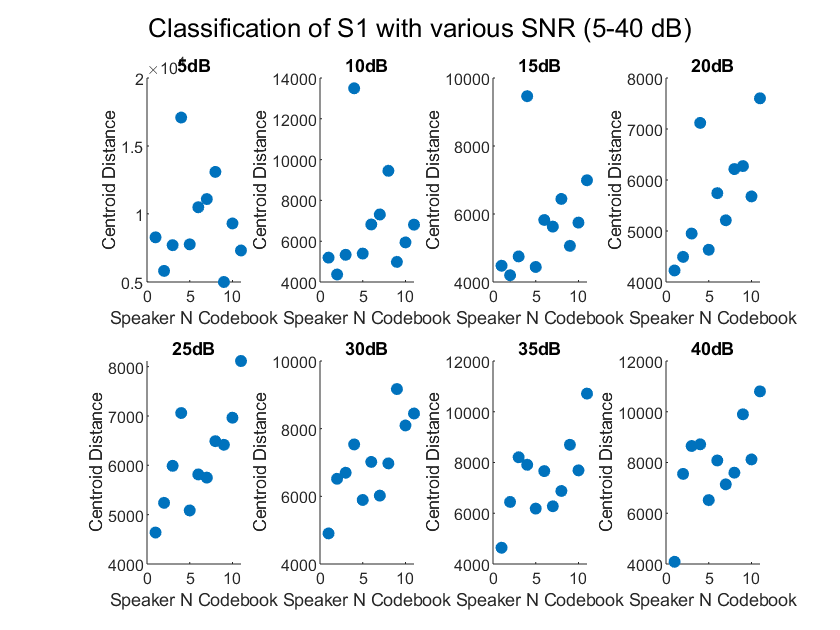

similarityValues1_5 = similarityToAllCodebooks(cepsCoeff1_5,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_10 = similarityToAllCodebooks(cepsCoeff1_10,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_15 = similarityToAllCodebooks(cepsCoeff1_15,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_20 = similarityToAllCodebooks(cepsCoeff1_20,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_25 = similarityToAllCodebooks(cepsCoeff1_25,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_30 = similarityToAllCodebooks(cepsCoeff1_30,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_35 = similarityToAllCodebooks(cepsCoeff1_35,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
similarityValues1_40 = similarityToAllCodebooks(cepsCoeff1_40,83,26,32,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11);
f = figure();
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,1);
scatter([1:11],similarityValues1_5,'filled');
title('5dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,2);
scatter([1:11],similarityValues1_10,'filled');
title('10dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,3);
scatter([1:11],similarityValues1_15,'filled');
title('15dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,4);
scatter([1:11],similarityValues1_20,'filled');
title('20dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,5);
scatter([1:11],similarityValues1_25,'filled');
title('25dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,6);
scatter([1:11],similarityValues1_30,'filled');
title('30dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,7);
scatter([1:11],similarityValues1_35,'filled');
title('35dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');
sgtitle('Classification of S1 with various SNR (5-40 dB)');
subplot(2,4,8);
scatter([1:11],similarityValues1_40,'filled');
title('40dB');
xlabel('Speaker N Codebook');
ylabel('Centroid Distance');

%-------------------Local Functions-------------------

function [N,M,signalframes] = createFrames(signal)
    N = 256;
    M = 100;
    signallength = length(signal);
    i = 1;
    count = 1;
    while(i+N < signallength)
        signalframes(count,:) = signal(i:i+N-1);
        i = i + N - M;
        count = count + 1;
    end
end

function [signalframecount,signalframesWindow] = applyWindow(signalframes,N)
    for i = [0:N-1]
        w(i+1) = 0.54 - 0.46*cos((2*pi*i)/(N-1));
    end
    signalframecount = length(signalframes(:,1));
    disp(signalframecount);
    
    for i = [1:signalframecount]
        signalframesWindow(i,:) = w.*signalframes(i,:);
    end
end

function [signalframesWindowFFT256] = periodogramFFT(signalframecount,signalframesWindow)
    for i = [1:signalframecount]
        signalframesWindowFFT512(i,:) = fft(signalframesWindow(i,:),512);
        signalframesWindowFFT256(i,:) = signalframesWindowFFT512(i,[1:256]);
    end
end

function [signalframespower] = getPower(N,signalframecount,signalframesWindowFFT256)
    for i = [1:signalframecount]
        signalframespower(i,:) = (1/N)*(abs(signalframesWindowFFT256(i,:)).^2);
    end
end

function [H,mN] = generateMelFilters(N,Fs)
    mN = 26;
    lowerFreqF = 300;%Hz
    upperFreqF = 6250;%Hz
    lowerFreqM = 1125*log(1+(lowerFreqF/700));%lower in mels
    upperFreqM = 1125*log(1+(upperFreqF/700));%upper in mels
    %Generate mN points inbetween lower upper in mels scale
    m = linspace(lowerFreqM,upperFreqM,mN+2);
    h = 700*(exp(m/1125)-1);%get back into hz scale (should be between 300-8000Hz)
    %get hz to closest fft bin
    %f(i) = floor((nfft+1)*h(i)/samplerate)
    f = floor(((512+1)*h)/Fs);
    for i = [1:mN]%Generate mN filters
        H(i,[1:f(i)]) = 0;
        for k = [f(i):f(i+1)]
        %H(i,[f(i):f(i+1)]) = (i-f(i))/(f(i+1)-f(i));
            H(i,k) = (k-f(i))/(f(i+1)-f(i));
        end
        for k = [f(i+1):f(i+2)]
        %H(i,[f(i+1):f(i+2)]) = (f(i+2)-i)/(f(i+2)-f(i+1));
            H(i,k) = (f(i+2)-k)/(f(i+2)-f(i+1));
        end
        H(i,[f(i+2):N]) = 0;
    end
end


function [melFilterPower] = applyFilterOnPower(mN,signalframespower,signalframecount,H)
    for f = [1:signalframecount]%for each frame
        for i = [1:mN]
            multPowerFilter = H(i,:).*signalframespower(f,:);
            melFilterPower(f,i) = sum(multPowerFilter);
        end
    end
end

function [cepstralCoeff] = cepstrum(signalframecount,melFilterPower)
    for f = [1:signalframecount]
        melFilterPowerLog(f,:) = log(melFilterPower(f,:));%take log
        cepstralCoeff(f,:) = dct(melFilterPowerLog(f,:));
    end
    %return cepstralCoeff;
end

function [cepstralCoeff] = generateCepstrum(signal,Fs)
    [N,M,signalframes] = createFrames(signal);
    [signalframecount,signalframesWindow] = applyWindow(signalframes,N);
    [signalframesWindowFFT256] = periodogramFFT(signalframecount,signalframesWindow);
    [signalframespower] = getPower(N,signalframecount,signalframesWindowFFT256);
    [H,mN] = generateMelFilters(N,Fs);
    [melFilterPower] = applyFilterOnPower(mN,signalframespower,signalframecount,H);
    [cepstralCoeff] = cepstrum(signalframecount,melFilterPower);
    %[cepstralCoeff] = cepstrum();
end

function [m, p, DistHist]=vqsplit(X,L)%--------------------------------------
% Vector Quantization: K-Means Algorithm with Spliting Method for Training
% NOT TESTED FOR CODEBOOK SIZES OTHER THAN POWERS OF BASE 2, E.G. 256, 512, ETC
% (Saves output to a mat file (CBTEMP.MAT) after each itteration, so that if
% it is going too slow you can break it (CTRL+C) without losing your work
% so far.)
% [M, P, DH]=VQSPLIT(X,L)
% 
% or
% [M_New, P, DH]=VQSPLIT(X,M_Old)   In this case M_Old is a codebook and is
%                                   retrained on data X
% 
% inputs:
% X: a matrix each column of which is a data vector
% L: codebook size (preferably a power of 2 e.g. 16,32 256, 1024) (Never
% tested for other values!
% 
% Outputs:
% M: the codebook as the centroids of the clusters
% P: Weight of each cluster the number of its vectors divided by total
%       number of vectors
% DH: The total distortion history, a vector containing the overall
% distortion of each itteration
%
% Method:
% The mean vector is split to two. the model is trained on those two vectors
% until the distortion does not vary much, then those are split to two and
% so on. until the disired number of clusters is reached.
% Algorithm:
% 1. Find the Mean
% 2. Split each centroid to two
% 3. Assign Each Data to a centroid
% 4. Find the Centroids
% 5. Calculate The Total Distance
% 6. If the Distance has not changed much
%       if the number of Centroids is smaller than L2 Goto Step 2
%       else Goto 7
%    Else (the Distance has changed substantialy) Goto Step 3
% 7. If the number of Centroids is larger than L
%    Discard the Centroid with (highest distortion OR lowest population)
%    Goto 3
% 8. Calculate the Variances and Cluster Weights if required
% 9. End
%
% Esfandiar Zavarehei, Brunel University
% May-2006
e=.01; % X---> [X-e*X and X+e*X] Percentage for Spliting
eRed=0.75; % Rate of reduction of split size, e, after each spliting. i.e. e=e*eRed;
DT=.005; % The threshold in improvement in Distortion before terminating and spliting again
DTRed=0.75; % Rate of reduction of Improvement Threshold, DT, after each spliting
MinPop=0.10; % The population of each cluster should be at least 10 percent of its quota (N/LC)
             % Otherwise that codeword is replaced with another codeword
d=size(X,1); % Dimension
N=size(X,2); % Number of Data points
isFirstRound=1; % First Itteration after Spliting
if numel(L)==1
    M=mean(X,2); % Mean Vector
    CB=[M*(1+e) M*(1-e)]; % Split to two vectors
else
    CB=L; % If the codebook is passed to the function just train it
    L=size(CB,2);
    e=e*(eRed^fix(log2(L)));
    DT=DT*(DTRed^fix(log2(L)));
end
LC=size(CB,2); % Current size of the codebook
Iter=0;
Split=0;
IsThereABestCB=0;
maxIterInEachSize=20; % The maximum number of training itterations at each 
                      % codebook size (The codebook size starts from one 
                      % and increases thereafter)
EachSizeIterCounter=0;
while 1
    %Distance Calculation
    [minIndx, dst]=VQIndex(X,CB); % Find the closest codewords to each data vector
    ClusterD=zeros(1,LC);
    Population=zeros(1,LC);
    LowPop=[];
    % Find the Centroids (Mean of each Cluster)
    for i=1:LC
        Ind=find(minIndx==i);
        if length(Ind)<MinPop*N/LC % if a cluster has very low population just remember it
            LowPop=[LowPop i];
        else
            CB(:,i)=mean(X(:,Ind),2);
            Population(i)=length(Ind);
            ClusterD(i)=sum(dst(Ind));
        end        
    end
    if ~isempty(LowPop)
        [temp MaxInd]=maxn(Population,length(LowPop));
        CB(:,LowPop)=CB(:,MaxInd)*(1+e); % Replace low-population codewords with splits of high population codewords
        CB(:,MaxInd)=CB(:,MaxInd)*(1-e);
        
        %re-train
        [minIndx, dst]=VQIndex(X,CB);
        ClusterD=zeros(1,LC);
        Population=zeros(1,LC);
        
        for i=1:LC
            Ind=find(minIndx==i);
            if ~isempty(Ind)
                CB(:,i)=mean(X(:,Ind),2);
                Population(i)=length(Ind);
                ClusterD(i)=sum(dst(Ind));
            else %if no vector is close enough to this codeword, replace it with a random vector
                CB(:,i)=X(:,fix(rand*N)+1);
                disp('A random vector was assigned as a codeword.')
                isFirstRound=1;% At least another iteration is required
            end                
        end
    end
    Iter=Iter+1;
    if isFirstRound % First itteration after a split (dont exit)
        TotalDist=sum(ClusterD(~isnan(ClusterD)));
        DistHist(Iter)=TotalDist;
        PrevTotalDist=TotalDist;        
        isFirstRound=0;
    else
        TotalDist=sum(ClusterD(~isnan(ClusterD)));  
        DistHist(Iter)=TotalDist;
        PercentageImprovement=((PrevTotalDist-TotalDist)/PrevTotalDist);
        if PercentageImprovement>=DT %Improvement substantial
            PrevTotalDist=TotalDist; %Save Distortion of this iteration and continue training
            isFirstRound=0;
        else%Improvement NOT substantial (Saturation)
            EachSizeIterCounter=0;
            if LC>=L %Enough Codewords?
                if L==LC %Exact number of codewords
                    disp(TotalDist)
                    break
                else % Kill one codeword at a time
                    [temp, Ind]=min(Population); % Eliminate low population codewords
                    NCB=zeros(d,LC-1);
                    NCB=CB(:,setxor(1:LC,Ind(1)));
                    CB=NCB;
                    LC=LC-1;
                    isFirstRound=1;
                end
            else %If not enough codewords yet, then Split more
                CB=[CB*(1+e) CB*(1-e)];
                e=eRed*e; %Split size reduction
                DT=DT*DTRed; %Improvement Threshold Reduction
                LC=size(CB,2);
                isFirstRound=1;
                Split=Split+1;
                IsThereABestCB=0; % As we just split this codebook, there is no best codebook at this size yet
                disp(LC)
            end
        end
    end    
    if ~IsThereABestCB
        BestCB=CB;
        BestD=TotalDist;
        IsThereABestCB=1;
    else % If there is a best CB, check to see if the current one is better than that
        if TotalDist<BestD
            BestCB=CB;
            BestD=TotalDist;
        end
    end
    EachSizeIterCounter=EachSizeIterCounter+1;
    if EachSizeIterCounter>maxIterInEachSize % If too many itterations in this size, stop training this size
        EachSizeIterCounter=0;
        CB=BestCB; % choose the best codebook so far
        IsThereABestCB=0;
        if LC>=L %Enough Codewords?
            if L==LC %Exact number of codewords
                disp(TotalDist)
                break
            else % Kill one codeword at a time
                [temp, Ind]=min(Population);
                NCB=zeros(d,LC-1);
                NCB=CB(:,setxor(1:LC,Ind(1)));
                CB=NCB;
                LC=LC-1;
                isFirstRound=1;
            end
        else %Split
            CB=[CB*(1+e) CB*(1-e)];
            e=eRed*e; %Split size reduction
            DT=DT*DTRed; %Improvement Threshold Reduction
            LC=size(CB,2);
            isFirstRound=1;
            Split=Split+1;
            IsThereABestCB=0;
            disp(LC)
        end
    end        
    disp(TotalDist)
    p=Population/N;
    save CBTemp CB p DistHist
end
m=CB;
p=Population/N;
disp(['Iterations = ' num2str(Iter)])
disp(['Split = ' num2str(Split)])

end


function [v, i]=maxn(x,n)%-------------------------------------------------------
% [V, I]=MAXN(X,N)
% APPLY TO VECTORS ONLY!
% This function returns the N maximum values of vector X with their indices.
% V is a vector which has the maximum values, and I is the index matrix,
% i.e. the indices corresponding to the N maximum values in the vector X
if nargin<2
    [v, i]=max(x); %Only the first maximum (default n=1)
else
    n=min(length(x),n);
    [v, i]=sort(x);
    v=v(end:-1:end-n+1);
    i=i(end:-1:end-n+1);    
end
end

function [I, dst]=VQIndex(X,CB)%------------------------------------------------- 
% Distance function
% Returns the closest index of vectors in X to codewords in CB
% In other words:
% I is a vector. The length of I is equal to the number of columns in X.
% Each element of I is the index of closest codeword (column) of CB to
% coresponding column of X
L=size(CB,2);
N=size(X,2);
LNThreshold=64*10000;
if L*N<LNThreshold
    D=zeros(L,N);
    for i=1:L
        D(i,:)=sum((repmat(CB(:,i),1,N)-X).^2,1);
    end
    [dst I]=min(D);
else
    I=zeros(1,N);
    dst=I;
    for i=1:N
        D=sum((repmat(X(:,i),1,L)-CB).^2,1);
        [dst(i) I(i)]=min(D);
    end
end
end

function [I, dist]=VQLSFSpectralIndex(X,CB,W)%--------------------------------------
% If your codewords are LSF coefficients, You can use this function instead of VQINDEX
% This is for speech coding
% I=VQLSFSPECTRALINDEX(X,CB,W)
% Calculates the nearest set of LSF coefficients in the codebook CB to each
% column of X by calculating their LP spectral distances.
% I is the index of the closest codeword, X is the set of LSF coefficients
% (each column is a set of coefficients) CB is the codebook, W is the
% weighting vector, if not provided it is assumed to be equal to ones(256,1)
% Esfandiar Zavarehei
% 9-Oct-05
if nargin<3
    L=256;
    W=ones(L,1);
else
    if isscalar(W)
        L=W;
        W=ones(L,1);
    elseif isvector(W)
        W=W(:);
        L=length(W);
    else
        error('Invalid input argument. W should be either a vector or a scaler!')
    end
end
NX=size(X,2);
NCB=size(CB,2);
AX=lsf2lpc(X);
ACB=lsf2lpc(CB);
D=zeros(NCB,1);
w=linspace(0,pi,L+1);
w=w(1:end-1);
N=size(AX,2)-1;
WFZ=zeros(N+1,L);
IMAGUNIT=sqrt(-1);
for k=0:N
    WFZ(k+1,:)=exp(IMAGUNIT*k*w);
end
SCB=zeros(L,NCB);
for i=1:NCB
    SCB(:,i)=(1./abs(ACB(i,:)*WFZ));
end
I=zeros(1,NX);
dist=zeros(1,NX);
for j=1:NX
    SX=(1./abs(AX(j,:)*WFZ))';    
    for i=1:NCB
        D(i)=sqrt(sum(((SX-SCB(:,i)).^2).*W));
    end
    [dist(j), I(j)]=min(D);
end
end


function [values] = similarityToAllCodebooks(cepsCoeff,frameNumber,melFiltersNum,codebookNum,c1,c2,c3,c4,c5,c6,c7,c8,c9,c10,c11)
    
   values(1) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c1,codebookNum);
   values(2) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c2,codebookNum);
   values(3) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c3,codebookNum);
   values(4) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c4,codebookNum);
   values(5) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c5,codebookNum);
   values(6) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c6,codebookNum);
   values(7) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c7,codebookNum);
   values(8) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c8,codebookNum);
   values(9) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c9,codebookNum);
   values(10) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c10,codebookNum);
   values(11) =  similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,c11,codebookNum);
end

function [score] = similarityToCodebook(cepsCoeff,frameNumber,melFiltersNum,codebook,codebookNum)
    score = 0;
    centroidCompare = whichCentroidToComputeDist(cepsCoeff,frameNumber,melFiltersNum,codebook,codebookNum);
    for mN = [1:melFiltersNum]
        for frames = [1:frameNumber]
           score = score + abs(cepsCoeff(frames,mN) - codebook(mN,centroidCompare(frames,mN)));
        end
    end
end

function [centroidCompare] = whichCentroidToComputeDist(cepsCoeff,frameNumber,melFiltersNum,codebook,codebookNum)
    for mN = [1:melFiltersNum]
        for frames = [1:frameNumber]
            for c = [1:codebookNum]
                temp(c) = abs(cepsCoeff(frames,mN) - codebook(mN,c));
            end
            [x,i] = min(temp);
            centroidCompare(frames,mN) = i;
        end
    end
end

function mfcc_array = mfcc(s,fs,nfilt,norm,lift) % 'y' or normalization and 'l' for liftering
    if norm == 'y'
        s = normalize(s);
    end
    t1 = 0:1/fs:length(s)/fs-1/fs;
    %plot(t1,s),title('s1 audio input')
    N = 256;
    M = 100;
    n = 0:255;
    
    numFrames = floor((length(s)-N)/(N-M))+1;
    frames = zeros(numFrames,N);
    
    startindex = 1;
    endindex = N;
    w = hamming(N);
    y = zeros(numFrames,N);
    frames_fft = zeros(numFrames,N);
    P = zeros(numFrames,N);
    Pgram= zeros(numFrames,length(s));
    for k = 1:numFrames
        frames(k,:) = s(startindex:endindex);
        frames(k,:) = frames(k,:);
        startindex = startindex+N-M;
        endindex = startindex+N-1;
        % apply window
        y(k,:) = frames(k,:).*w';
        % compute FFT of each frame
        frames_fft(k,:) = fft(y(k,:));
        % compute periodogram
        P(k,:) = ((abs(exp(-1i.*M.*n.*(k-1)).*frames_fft(k,:))).^2)/N;
        zp = zeros(1,(k-1).*M);
        Pgram(k,:) = [zp P(k,:) zeros(1,abs(length(s)-length(zp)-length(P(k,:))))];
    end
    Pgram_sum = sum(Pgram);
    %plot(abs(Pgram_sum))
    start_freq = 300;
    end_freq = fs/2;
    m_start = 2595.*log10(1+start_freq/700);
    m_end = 2595.*log10(1+end_freq./700);
    m = linspace(m_start,m_end,nfilt+2);
    f_Hz = 700*(10.^(m./2595)-1);
    f_bin = floor((2*N+1).*f_Hz/fs);
    
    % generate filter bank
    fbank = zeros(20,256);
    for mel_k = 1:nfilt
        f_m_left = f_bin(mel_k);
        f_m_center = f_bin(mel_k+1);
        f_m_right = f_bin(mel_k+2);
        
        for k = f_m_left:f_m_center
            fbank(mel_k,k) = (k-f_bin(mel_k))/(f_bin(mel_k+1)-f_bin(mel_k));
            if fbank(mel_k,k)<=0
                fbank(mel_k,k)=0;
            end
        end
        for k = f_m_center:f_m_right
            fbank(mel_k,k) = (f_bin(mel_k+2)-k)/(f_bin(mel_k+2)-f_bin(mel_k+1));
            if fbank(mel_k,k)<=0
                fbank(mel_k,k)=0;
            end
        end
    end
    %plot(n,fbank)
    mfcc_array = zeros(numFrames,nfilt);
    for k = 1:numFrames
        mfcc_array(k,:) = dct(10*log10(fbank*P(k,:)'));
    end 
    if lift == 'l'
        w=1+(15/2)*sin((1:nfilt)*pi/15);
        mfcc_array = w.*mfcc_array;
    end
    %surf(-1*mfcc_array,'EdgeColor','none');   
    axis xy; axis tight; colormap default; view(0,90); colorbar;
end